# Microarray Data Analysis

The following study was used: [http://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE7307](http://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE7307) The study contains gene expression profiles of 677 samples from 125 distinct tissue types.

Analysis tasks were performed as described below 

diseasegene.txt

commongenes.txt

**Objectives:**

- Understand the gene expression using microarray 

- Differential gene expression

- Familiar with the GEO repository hosted at NCBI [http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)

- Understand the GEO structure  GSE and GPL

- Download GEO data

- Map container containers.Map()

- Logical indexing

- Clustering and PCA analysis

- Volcano plot 

%Download the data and parse it, change the d (gse.data) rownames to gene names from gpl
gse=bmes_downloadandparsegse7('GSE7307');

Reading /private/var/folders/g8/824tqwk50c17j0sh1y69p4z5x108l_/T/GSE7307.txt ...


d = gse.Data;
I= genevarfilter(d, 'Percentile',99); 
d = d( I, :);

% d: 547x677 datamatrix with Header information
headerInfo = gse.Header.Samples.characteristics_ch1;
% Diagnostic information for all data
info = gse.Header.Samples.characteristics_ch1(1,:);
% Platform ID from gse
gse.Header.Series.platform_id;

% Download the GPL data
gpl = bmes_downloadandparsegpl('GPL570');
%Information we get from each probe:
columnNames = gpl.ColumnNames;


# Translate probesets to gene symbols  ( the goal is to replace the d.rownames with the gene symbol from gpl)

  !platform_table_begin (probe id links gpl and gse data)



% Get the probe names and gene names from the gpl data set.
gplProbes = gpl.Data(:, strcmp(gpl.ColumnNames, 'ID'));
gplGenes  = gpl.Data(:, strcmp(gpl.ColumnNames, 'Gene Symbol'));
% Get the gene names from the gse data set. These should be the same as the
% gpl gene names from the gpl data set. Going to map between these to get
% identifiers that work with both. In the gse, each row is a gene. Each
% column is a tissue sample. In the gpl data, each row is a sample and the
% ID column has the probe names and the gene symbol name has the gene
% names.
gseProbes = d.rownames;

% Mapping. Create a matrix that will be used for mapping.
myMap = zeros(numel(gseProbes),1);
% Create a map based on the size of gplprobes.
map = containers.Map(gplProbes,1:numel(gplProbes));
for i=1:numel(gseProbes)
    if map.isKey(gseProbes{i})
        MAP_GSE_GPL(i) = map(gseProbes{i});
    end
end
% Make a copy in case some names were not matched. Gsegenes is a variable
% that contains all the probe names.Gsegenes is for indexing.
gseGenes = gseProbes;
% Gsegenes is now a matrix that has a list of gene names in an order.
gseGenes(find(MAP_GSE_GPL)) = gplGenes(MAP_GSE_GPL(find(MAP_GSE_GPL)));
% Replace data matrix so uses genes as row names
d = d.rownames(':',gseGenes);
d(1:6,1:5)

ans = 

                       GSM175786    GSM175787    GSM175788    GSM175789    GSM175790
    COX1               7299.3       8163.3       7576.5       8265.9       9381.4   
    ND2                5008.7       6286.8       4806.3       5473.9       8096.4   
    ATP6               6137.3       7005.2       6242.7       6779.1       7787.3   
    COX2               4826.2       5591.4       4839.3       5527.7         8120   
    COX2               5614.3       6499.1       5614.2       6567.4       8851.8   
    ND3 /// SH3KBP1    6821.5       8005.9       7140.1       7758.9         9430   



# Clustering Samples (tissue type and disease state)

Use k means clustering method to group all gene expressions in 4 clusters. investigate for each cluster, do the samples from normal and disease  have similar overall expression profiles (for all 12 disease states)? 

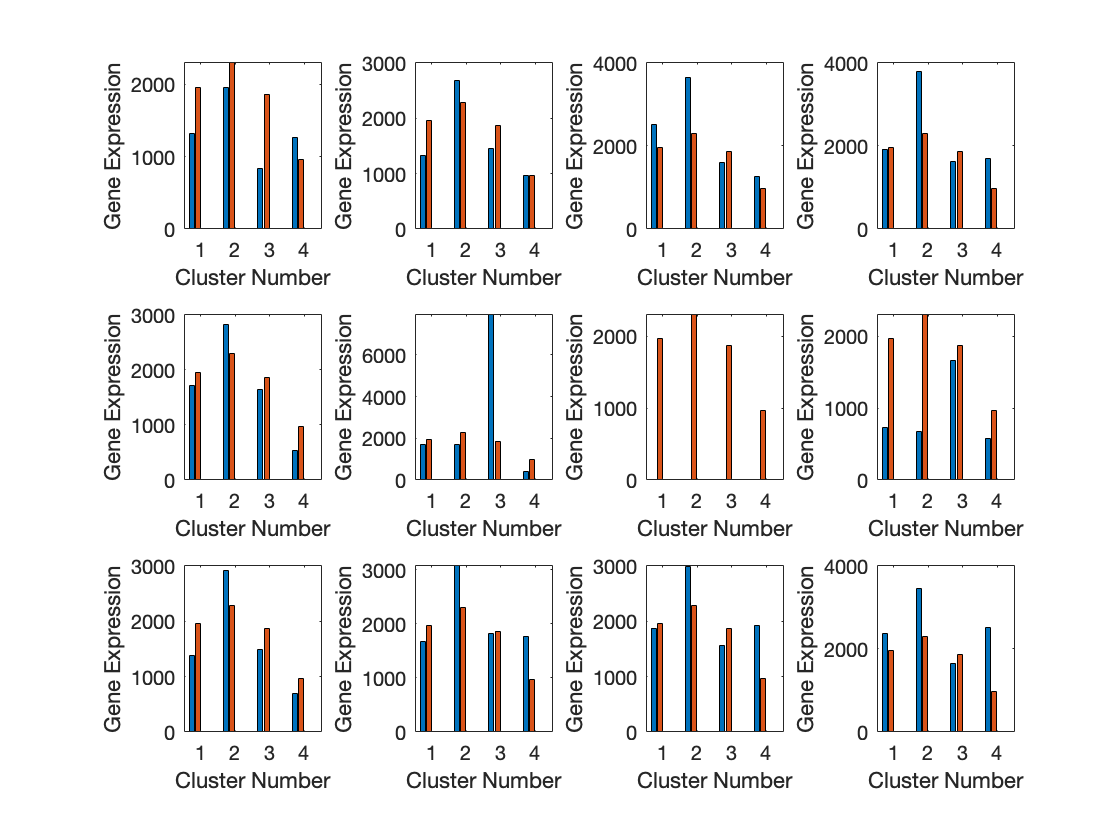

% Get the tissue and disease types that we're analyzing.
tissue = gse.Header.Samples.characteristics_ch1(1,:);
tissueType = unique(tissue); % total 125 tissue types
disease = gse.Header.Samples.characteristics_ch1(4,:);
diseaseType = unique(disease); % total 12 disease, diseaseType(7) is normal

% User clust to cluser the data in 4 clusters 
    clust = kmeans(d,4,'dist','corr');
    
% for each diseaseType investigate two groups IdiseaseSamp and Inormal
normaldisease = diseaseType{7};
for i = 1:numel(diseaseType)
    IdiseaseSamp = strcmp(disease,diseaseType(i)); % 1x677 logical array for patients with that disease. 
    Inormal = strcmp(disease,normaldisease); %  1x677 logical array for patients who are normal
    group1 = IdiseaseSamp; 
    group2 = Inormal;
   
% assign the index to Igroups and number to Igroups
    Igroups = zeros(1,numel(disease));
    Igroups(group1) = 1;
    Igroups(group2) = 2;

%distribute this data in averages to plots for each disease    
    davg = zeros(4,4);
    subplot(3,4,i)
    for i = 1:4 % within clusters
        for j= 1:2 % within groups
            % find the mean of all patients belong to the cluster ==i and group ==j
            davg(i,j) = mean(mean(d(clust==i,Igroups==j)));
        end
    end
    %Graphs the output in bar charts
    bar(davg)
    % title('Avg Exp Values for Clusters');
    xlabel('Cluster Number');
    ylabel('Gene Expression');
end

**Figure 1. **This figure is a representation of specific gene expression as related to the clustering performed on the data for each comparision of disease types. The cluster number is on the y-axis and the gene expression is on the x-axis. Each suplot is a disease type. 

## Conclusions:

For all disease types it can be concluded that the expression profiles of similar tissue types are about the same. In some cases this is not true, but overall the clustering does a pretty good job of identifying tissue types and matching them with similar gene expression values, comparitively. Importantly, in subplot 7 with only one set of data (disease type: normal), the comparison is to itself and therefore the data is overlapping.

Use k means clustering method to group all gene expressions in 4 clusters. Investigate for tissue type 1 of each disease type, within each cluster, do the samples from normal and disease state have similar overall expression profiles (for all 12 disease states)? 

    {[1]}    {'Disease type: Adenomyosis'}



    {[2]}    {'Disease type: BPH'}



    {[3]}    {'Disease type: Breast cancer'}



    {[4]}    {'Disease type: Endometriosis'}



    {[5]}    {'Disease type: Melanoma'}



    {[6]}    {'Disease type: Neuromuscular pain'}



    {[7]}    {'Disease type: Normal'}



    {[8]}    {'Disease type: Parkinson's disease'}



    {[9]}    {'Disease type: Prostate cancer'}



    {[10]}    {'Disease type: Prostate cancer - adjacent'}



    {[11]}    {'Disease type: Rheumatoid arthritis'}



    {[12]}    {'Disease type: Uterine fibroid'}



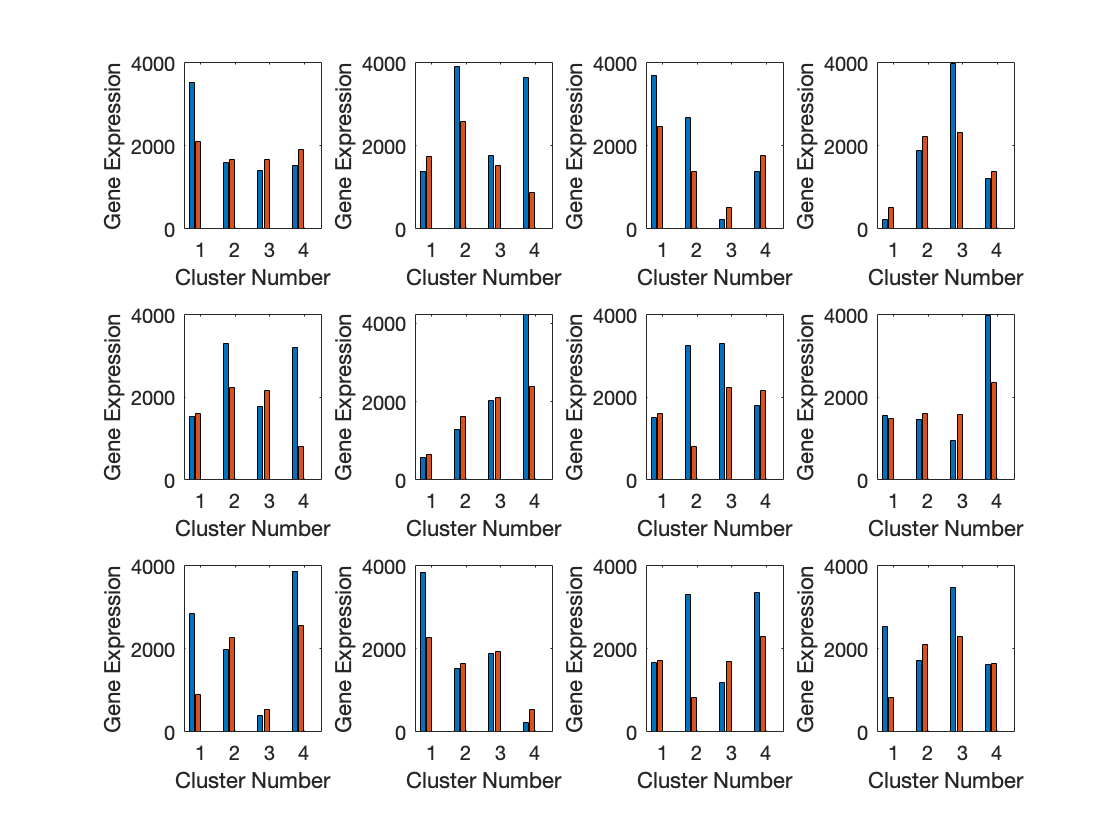


% Identify groups that you want to cluster in terms of diseases and tissue
% corelations
for i = 1:numel(diseaseType)
    IdiseaseSamp = strcmp(disease,diseaseType(i));
    diseaseTissue = unique(tissue(IdiseaseSamp));
    ItissueSamp = strcmpi(disease,diseaseTissue(1)); % define the logical array for the first tissue type of disseasetype(i)
    disp([i,diseaseType(i)]);
    ggroup1 = IdiseaseSamp & ItissueSamp; % define logical index array for patients with first tissue type of diseasetype (i) 
    ggroup2 = ~IdiseaseSamp & ItissueSamp; % define logical index array for noraml patients with first tissue type of diseasetype (i)
    IIgroups = zeros(1,numel(disease));
    IIgroups(ggroup1) = 1;
    IIgroups(ggroup2) = 2;
   
% User clust to cluser the data  
    clust = kmeans(d,4,'dist','corr');
%distribute this data in averages to plots for each disease    
    davg = zeros(4,4);
    subplot(3,4,i)
    for i = 1:4
        for j= 1:2
            davg(i,j) = mean(mean(d(clust==i,Igroups==j)));
        end
    end
    %Graphs the output in bar charts
    bar(davg)
    % title('Avg Exp Values for Clusters');
    xlabel('Cluster Number');
    ylabel('Gene Expression');
end

**Figure 2: **This figure is a representation of specific gene expression as related to the clustering performed on the data for each comparision of disease types for tissue type 1 of each disease type. The cluster number is on the y-axis and the gene expression is on the x-axis. Each suplot is a disease type. 

## Conclusions: 

For all 12 disease types it can be concluded that the expression profiles for tissue type1 are about the same. 

# Differential Gene Expression in Disease

What are the genes that are differentially expressed in each disease? For each disease, compare the disease samples with the normal samples of the same tissue. Save the results into an Excel worksheet named diseasegene, with the header row containing "disease", "gene", "pvalue", "negfoldchange". Only show significant genes. Get disease type

In this dataset, the gene expression number is not at a log scale.

disease = gse.Header.Samples.characteristics_ch1(4,:);
diseaseType = unique(disease);
%Find a unique list of all the disease states

diseasestates = [diseaseType(1:6) diseaseType(8:12)];
% diseasestates = [diseaseType(1)];
%Find a unique list of all the tissues
sampletissue = gse.Header.Samples.characteristics_ch1(1,:);
tissuetypes = unique(sampletissue);
exceldata = [];
%exceldata2 = []
%For each disease, grab the pvalues, nfc and unique gene and populate the
%data matrix excel data.

- 677 patients (677 columns) and each patient has a defined disease type and a tissue type. gse.Header.Samples.characteristics_ch1(4,:) and tissue type gse.Header.Samples.characteristics_ch1(1,:)

- unique 12 disease types (1-12) and redefine 11 disease states #1-6 and # 8-12 of the disease types plus #7 as normal 

- unique 125 tissue types

- For each disease state, there are associated tissue types from 125 tissue types

- **go through each disease state and its associated unique tissue types to compare the gene expression of normal tissue and disease tissue.**

- for example, disease state 1 "adenomyosis" has only one unique tissue type "myometrim", you will compare the gene expression between normal myometrim and disease myometrium.

- loop through disease states and unique tissue types associated with the disease states to find the significant genes. 

- everything is based on a logical index (1X677). 

- Inormal (1x677): indicates patients are normal; 

- Idisease: patients have a certain disease, 

- Itissuetype: patients have a certain tissue type

- **Idisease_tissue: patient with a certain disease and certain tissue type. **

- **Ibase: normal patients with certain tissue types; **

- write/record every significant gene in a text file. 

for i = 1:numel(diseasestates) % loop through disease states
    % Grab the logical indices for the specific disease
    Idisease = strcmp(disease,diseasestates(i));
    % These are the tissue types that have that disease
    corrtissuetypes = sampletissue(Idisease);
    % Unique tissue list for the disease we are looking at
    uniquetissuetype = unique(corrtissuetypes);
    %Find the indices of the normal samples
    Inormal = strcmp(disease,'Disease type: Normal');
    % This is the index for the tissue type were looking for
    % Itissuetype = strcmp(sampletissue,uniquetissuetype(1));
    % This is for multiple tissue types
    
    Itissuetype = zeros(1,size(sampletissue,2));
    for j = 1:numel(uniquetissuetype) % loop through the unique tissue types (uniquetissuetype) for disease i 
        Itissuetype = strcmp(sampletissue,uniquetissuetype(j));
        Ibase = Inormal & Itissuetype;
        Idisease_tissue= Idisease & Itissuetype;
    if sum(Idisease_tissue) < 1 || sum(Ibase) < 1
        'There is only one data set, so there is no significance'
    else
        %Find the significantly differently expressed genes in this disease
        
        [dpvals] = mattest(d(:,Idisease_tissue), d(:,Ibase),'permute',1000); % comapring normal  and disease with the same tissue type
        % find the mean of  each gene for Idisease_tissue
        negfcDisease = mean(d(:,Idisease_tissue),2);
        % find the mean  each gene for Ibase
        negfcNormal= mean(d(:,Ibase),2);
        negfc = zeros(size(negfcDisease,1), 1);
        
        for p=1:numel(negfcDisease) %assign the fold change
            negfc(p)=negfcDisease(p)/negfcNormal(p);
        end
       %write the negfc to dpvals with ColNames as negfc
        dpvals = [dpvals bioma.data.DataMatrix(negfcDisease,'ColNames',{'negfcDisease'})];
       %Find significant genes
        I = find(dpvals(:,1)<=0.01);
        
        %Initialize the data for population
        nsig=numel(I);
        xlsdata1 = cell(nsig, 4);
        Sdisease= diseasestates{i};
        
        % Get the data for each significant gene for disease state
        for k=1:nsig
            gene=dpvals.rownames{I(k)};
            if isempty(gene)
                gene = 'empty';
            end
            p=dpvals.double(I(k), 1);
            nfc=dpvals.double(I(k), 2);
            xlsdata1(k,:) = {Sdisease gene p nfc};
        end
        % Append the data matrix
        exceldata = [exceldata; xlsdata1]; 
    end
    end
    
    % Samples that have no disease, same tissue type as the diseased state being analyzed:
    %Ibase = Inormal & Itissuetype;
    % Samples that have disease
    %Idisease;
    % Mattest is finicky and only works if you are comparing a certain
    % number of data. Because I downsampled the data in the beginning, this
    % limits the number of comparison that can be made but also makes the
    % data easier to work with.
    
end

ans = 'There is only one data set, so there is no significance'

ans = 'There is only one data set, so there is no significance'

% grab the data for the excel file
diseasename = exceldata(:,1);
genesymbol = exceldata(:,2);
pvalue = exceldata(:,3);
fc = exceldata(:,4);
% for macs, you can use xlswrite for a combination of text and numbers. I
% used a text writing code and manually changed it to an excel file
% instead.
% write it to diseasegene.txt
T = table(diseasename, genesymbol,pvalue ,fc);
writetable(T,'diseasegene.txt')

# Commonly Altered Genes in Diseases

Now, based on the above results, we will ask the question: Are there any genes commonly differentially expressed for different diseases? For each of the differentially expressed genes you found, report the number of diseases they are involved in. Save the results into an Excel worksheet named commongenes, with the header row containing "gene", "numdiseases", "diseaselist" (CSV of diseases that the go term is found in).

%Find a unique list of genes
significantgenes = unique(genesymbol);
%Initialize data matrices
genes = cell(numel(significantgenes,1));
numdiseases = zeros(numel(significantgenes,1));
diseaselist = cell(numel(significantgenes,1));
% Run through the significant genes and grab the number of diseases they
% were involved in by indexing for the gene and summing the number of
% "ones" where it is true. Then get the list of genes by combining the
% disease names into one cell.
for i=1:numel(significantgenes)
    genes(i) = significantgenes(i);
    Isig_genes = strcmp(genesymbol,significantgenes(i));
    corrdisease = diseasename(Isig_genes);
    numdiseases(i) = sum(Isig_genes);
    diseasecell = strjoin(corrdisease);
    diseaselist(i) = cell({diseaselist});
end
% Get the data from here and make it able to write into a table.
genes= genes';
numdiseases = numdiseases';
diseaselist = diseaselist';
%write in a text file because mac's cant use xlswrite
T2 = table(genes,numdiseases,diseaselist);
writetable(T2,'commongenes.txt')